clear; clc; close all

1

A = eye(4)*3;
v = [1:4]';
a = dot(v,v)

a = 30

B = v*v'

B =      1     2     3     4
     2     4     6     8
     3     6     9    12
     4     8    12    16


C = A*B

C =      3     6     9    12
     6    12    18    24
     9    18    27    36
    12    24    36    48


[V,D] = eig(C)

V =     0.3996    0.8944   -0.0837    0.1826
    0.7992   -0.4472   -0.1673    0.3651
   -0.4037   -0.0000   -0.7328    0.5477
   -0.1967    0.0000    0.6542    0.7303


D =    -0.0000         0         0         0
         0   -0.0000         0         0
         0         0    0.0000         0
         0         0         0   90.0000


e = eig(C)

e =    -0.0000
   -0.0000
    0.0000
   90.0000


Es gibt fehler, wenn der Computer real-numbter speichert.

无误差结果：

syms lambda
I = eye(size(C));
lambda_AS = solve(det(lambda*I-C)==0, lambda);

x = (C-A)\(a*v)

x =     0.3448
    0.6897
    1.0345
    1.3793


C(:,2) = v

C =      3     1     9    12
     6     2    18    24
     9     3    27    36
    12     4    36    48


b = C(3,:)'

b =      9
     3
    27
    36


c = [10:.5:100]

c =    10.0000   10.5000   11.0000   11.5000   12.0000   12.5000   13.0000   13.5000   14.0000   14.5000   15.0000   15.5000   16.0000   16.5000   17.0000   17.5000   18.0000   18.5000   19.0000   19.5000   20.0000   20.5000   21.0000   21.5000   22.0000   22.5000   23.0000   23.5000   24.0000   24.5000   25.0000   25.5000   26.0000   26.5000   27.0000   27.5000   28.0000   28.5000   29.0000   29.5000   30.0000   30.5000   31.0000   31.5000   32.0000   32.5000   33.0000   33.5000   34.0000   34.5000


f = c.*(5+c)+1./c+2.^c

f = 	1.0e+30 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


lf = size(f,2)

lf = 181

2

a = rand(1,1000)

a =     0.1144    0.6874    0.4529    0.8437    0.1929    0.6691    0.5375    0.4897    0.3029    0.9465    0.0754    0.3381    0.5172    0.9990    0.1612    0.1713    0.1587    0.2773    0.7307    0.6649    0.1602    0.0286    0.9275    0.7445    0.6030    0.3596    0.6232    0.4039    0.6486    0.5610    0.1954    0.0825    0.7277    0.5214    0.5167    0.0256    0.4647    0.4982    0.2478    0.8386    0.9321    0.9867    0.6582    0.2449    0.4902    0.6351    0.0571    0.0863    0.1923    0.2399


if a(1)>=.5
    disp 'a1 >= 0.5'
else
    disp 'a1 < 0.5'
end

a1 < 0.5


n05 = numel(a(a>=.5))

n05 = 509

found = false

found = logical
   0


for i=[1:1000]
    if a(i)>.499 && a(i)<.501
        disp(i)
        disp(a(i))
        found = true;
        break
    end
end

   339



    0.4995



if ~found
    disp  'Kein Element 0.499 <= a_i <= 0.501'
end
for n=[1:5]
    facultaet(n)
end

ans = 1

ans = 2

ans = 6

ans = 24

ans = 120

3

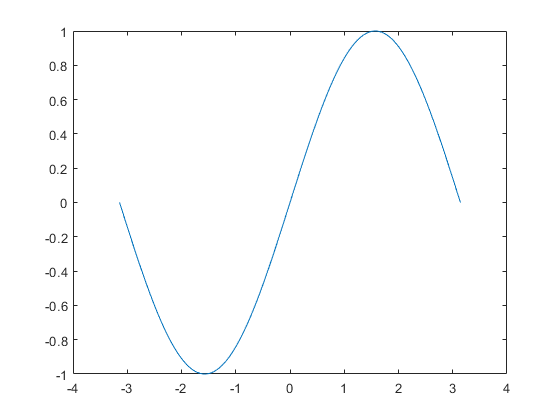

x = linspace(-pi,pi,200);
f = sin(x);
plot(x,f)

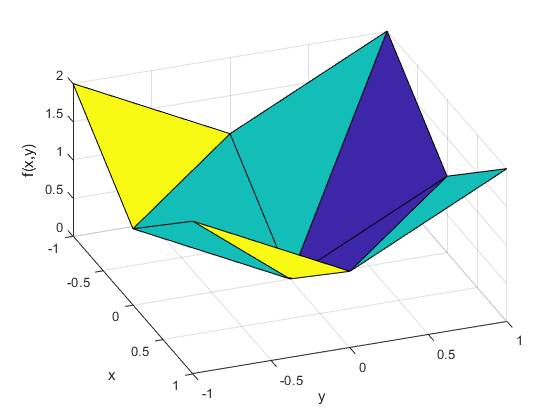


x = [-1 0 1];
[x,y]=meshgrid(x,x);
nodes = [x(:),y(:)];
elements = [1 4 5 2
    2 5 6 3
    4 7 8 5
    5 8 9 6];
sol = (x.^2+y.^2);
sol = sol(:);
quadplot(nodes,elements,sol)
xlabel('x')
ylabel('y')
zlabel('f(x,y)')